# Parametric Curves 

A more general representation of a curve involves expressing its coordinates in terms of another independent variable or parameter as follows


$$x = f(u), y = g(u), u \in [a,b]$$


Each value of u corresponds to a coordinate pair (f(u), g(u)). If we collect all the points defined by u in a specific interval, we get a parametric curve. For example, the definition


$$x = \cos u, y = \sin u, u \in [0, 2 \pi]$$


defines a unit circle, centered at the origin, which begins and ends at (1,0).

In order to visualize a parametric curve in Matlab, we first define a set of points on the u-domain.

u = linspace(0,2*pi,100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405


Next we define a function that accepts as u as input, and returns the coordinates x and y as output. The function is defined at the end of this script, but we include it here for clarity

**function [x,y] = circle(u)**

**    x = cos(u)**

**    y = sin(u)**

**end**

Now with the function defined, we can call it and then use **plot** as before, setting the axes so that it is clear that we have a circle.

[x,y] = circle(u)

x =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665


y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638


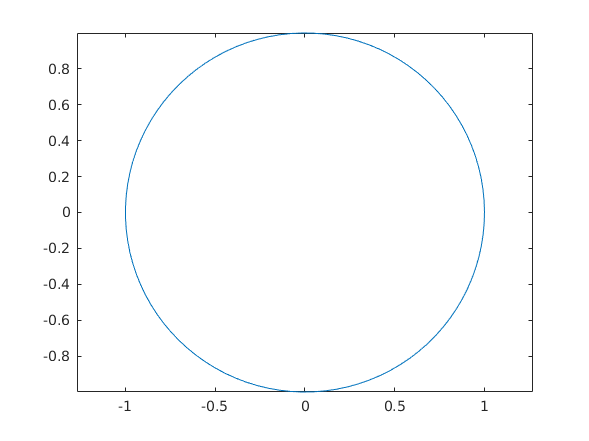

plot(x,y)
axis equal

As u increases from 0 to $2\pi$, the circle is traced out in counter-clockwise direction. The variable u can be interpreted as the angle from the x-axis to the current point on the circle.

**Exercise 1:** Look up the parametric equations that define an ellipse, and use the techniques developed here to visualize them. 

Solution: A quick browse of the internet shows that the parametric equations for an ellipse are


$$x = a \cos u, y = b \sin u, u \in [0,2\pi]$$


where a and b are parameters. Let's visualize the ellipse corresponding to a = 1 and b = 2

**Exercise 2:** A helix in 3D is often defined using the parametric equations


$$x = a \cos u, y = a \sin u, z = bu$$


where both a and b are positive. Use **plot3** to visualize the helix with a = 1 and b = 2 over the domain $u \in [0,10]$.

## Function definitions

function [x,y] = circle(u)
    % circle   Computes the coordinates of a parametric circle
    x = cos(u);
    y = sin(u);
end
